# Example 3.1 - Earth's gravity model

Construct a model of the earth's gravity using the first four **Jeffery's **constants in the series expansion of the gravitational potential. Compare the acceleration due to gravity with that of the spherical earth model $R=R_e =6378\ldotp 14\text{ }km$ for a trajectory in which the latitide (in degrees) varies with altitude, $h=r−R_e \text{ }$(in kilometers), as follows


$$\delta =h−100,\text{ }\left(0\le h\le 200km\right)$$


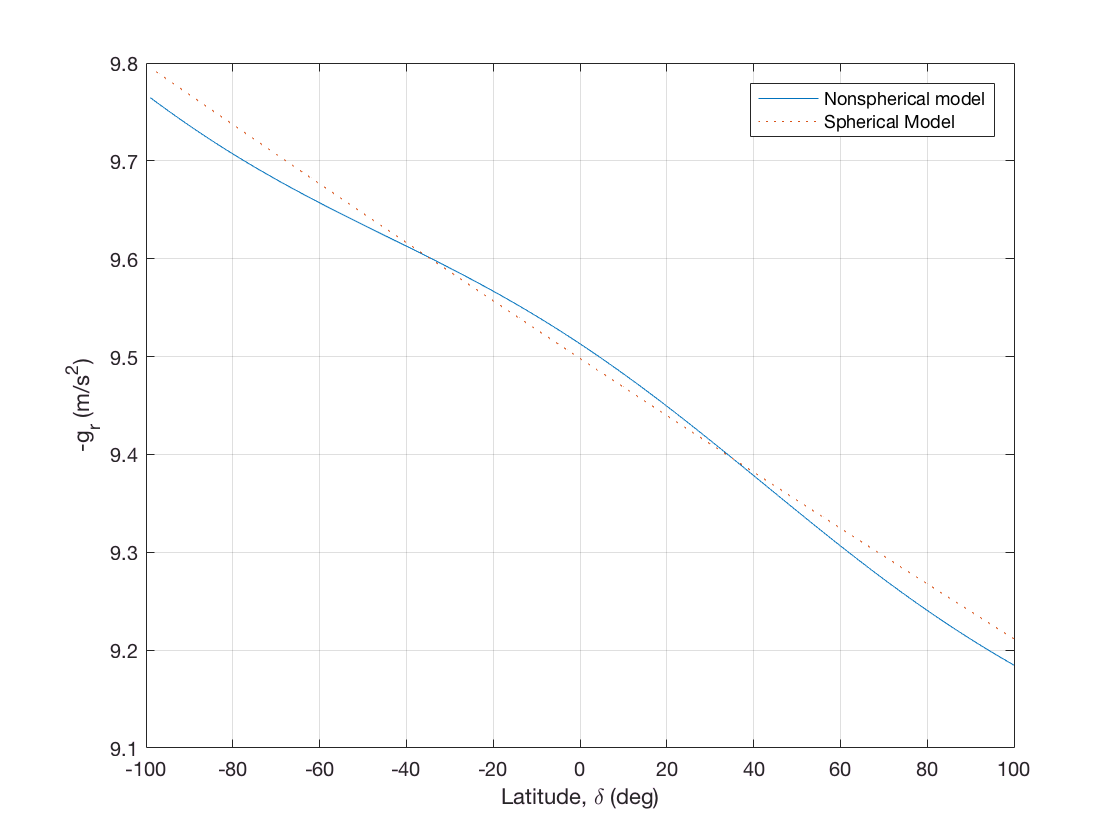

dtr = pi/180;
lat = 100*dtr;
r = 6578.14e3; %m
for i=1:200
   [GC(:,i), GN(:,i)]=gravity(r,lat);
   GS(:,i) = 3.986004e14/r^2;
   R(:,i) = r;
   LAT(:,i) = lat;
   
   r=r-1000;
   lat = lat - dtr;
end

plot(LAT/dtr,GC,LAT/dtr,GS,':')
xlabel('Latitude, \delta (deg)')
ylabel('-g_r (m/s^2)')
legend('Nonspherical model','Spherical Model')
grid on

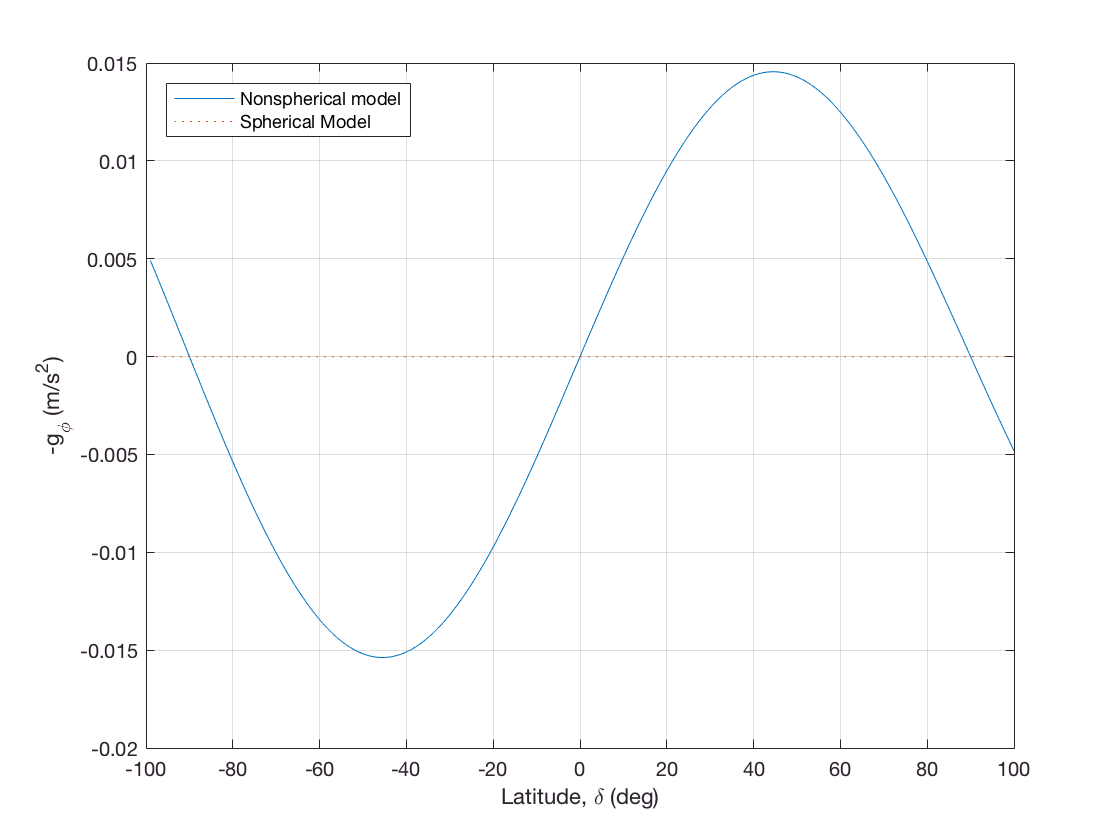


figure
plot(LAT/dtr,-GN,LAT/dtr,zeros(size(GS)),':')
xlabel('Latitude, \delta (deg)')
ylabel('-g_{\phi} (m/s^2)')
legend('Nonspherical model','Spherical Model','Location','northwest')
grid on